# Exercise 4.2.1

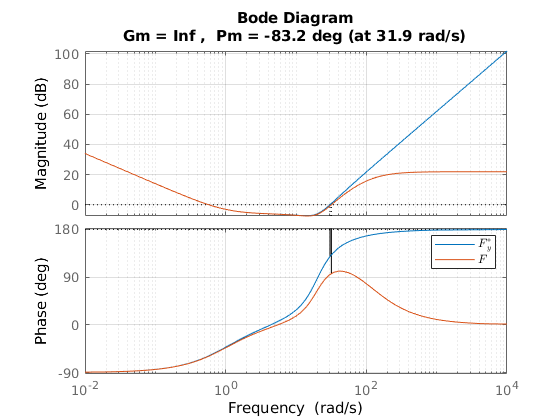

clear; clc;

s = tf('s');
G = 20 / ((s+1) * ((s/20)^2 + s/20+ 1));
Gd = 10 / (s + 1);

wc = 9.9437;
F_star = wc / (s*G);
p = 100;
p1 = p;
p2 = p;
F = F_star * p1 * p2 / ((s+p1) * (s+p2));

figure
hold on
margin(F_star)
margin(F)
grid on
hold off
legend({'$F\_{y}^{*}$','$F$'},'Interpreter','latex')

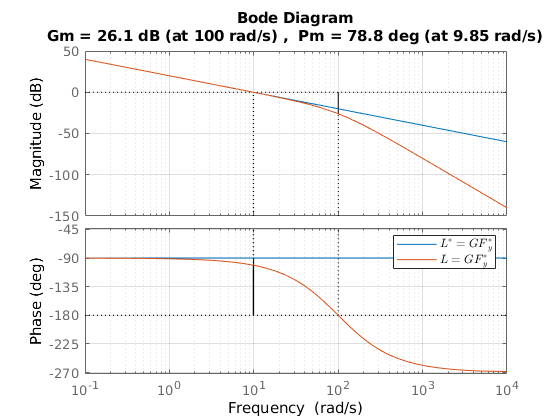


figure
hold on
margin(F_star*G)
margin(F*G)
grid on
legend({'$L^{*} = G F\_{y}^{*}$','$L = G F\_{y}^{*}$'},'Interpreter','latex')
hold off

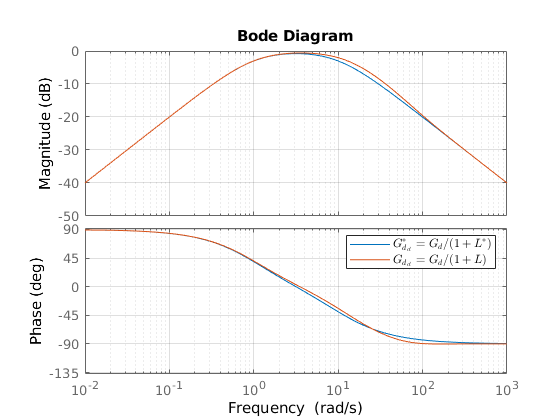


figure
hold on
bode(Gd / (1 + F_star*G))
bode(Gd / (1 + F*G))
grid on
legend({'$G\_{d\_{cl}}^{*} = G\_{d}/(1+L^{*})$','$G\_{d\_{cl}} = G\_{d}/(1+L)$'},'Interpreter','latex')
hold off

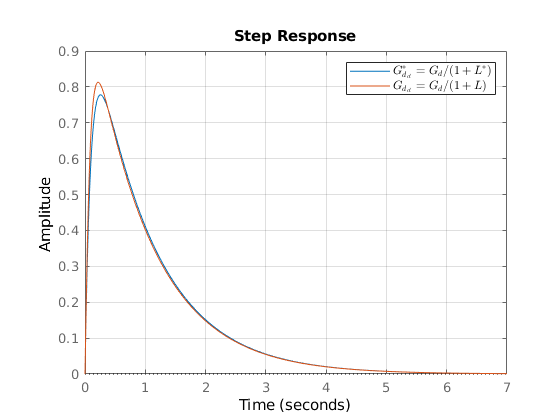


Gdcl_star = Gd / (1 + F_star*G);
Gdcl = Gd / (1 + F*G);
figure
hold on
step(Gdcl_star)
step(Gdcl)
legend({'$G\_{d\_{cl}}^{*} = G\_{d}/(1+L^{*})$','$G\_{d\_{cl}} = G\_{d}/(1+L)$'},'Interpreter','latex');
grid on
hold off

disp(stepinfo(Gdcl))

        RiseTime: 0
    SettlingTime: 4.2085
     SettlingMin: 5.1023e-04
     SettlingMax: 0.8129
       Overshoot: Inf
      Undershoot: 0
            Peak: 0.8129
        PeakTime: 0.2164



# Exercise 4.2.2

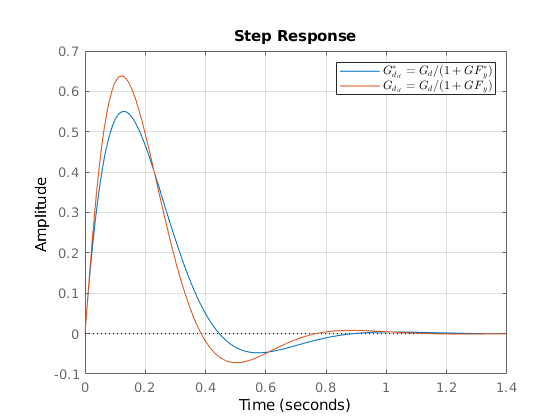

clear; clc;

s = tf('s');
G = 20 / ((s+1) * ((s/20)^2 + s/20+ 1));
Gd = 10 / (s + 1);

wi = 8;
Fy_star = (s + wi) * Gd / (s * G);

p = 100;
p1 = p;
p2 = p;

Fy = p1*p2*Fy_star/((s+p1)*(s+p2));

Gdcl_star = Gd / (1 + Fy_star*G);
Gdcl = Gd / (1 + Fy * G);

figure
hold on
step(Gdcl_star)
step(Gdcl)
legend({'$G\_{d\_{cl}}^{*} = G\_{d}/(1+GF\_{y}^{*})$','$G\_{d\_{cl}} = G\_{d}/(1+GF\_{y})$'},'Interpreter','latex');
grid on
hold off